%  ASEN-5044
% HWK 6 Q1

dt = 0.2;
A = [0,1;-100,-10];
B = [0;0];
Gamma = [0;1];
C = [1,0];
D = [0];
W = 10;
% generate DT model
Atilde = [A,B;C,D];
FG = expm( Atilde * dt);
g = Gamma * W * Gamma';
Z = dt * [-A, g;zeros(2,2), A'];
FGnoisy = expm(Z);
Ftr = FGnoisy(3:4,3:4);
FinvQ = FGnoisy(1:2,3:4);

Q = (Ftr)'* FinvQ;
disp("Q = "); disp (Q)

Q = 
    0.0040    0.0088
    0.0088    0.3760



 
% Q3
% part A
rng(s); % Reset random number gen
N = 100;
nlist = (1:1:N);
x0 = 1; n0 = 1; z0 = 1;
X = [x0;n0;z0];
H = eye(3);
Rnom = [8, 5.15, 6.5; 5.15, 5 ,-4.07; 6.5, -4.07, 50];
% get matrix sqrt of R
Sv = chol(Rnom,'lower');
disp ("Sv = "); disp (Sv)

Sv = 
    2.8284         0         0
    1.8208    1.2980         0
    2.2981   -6.3595    2.0677



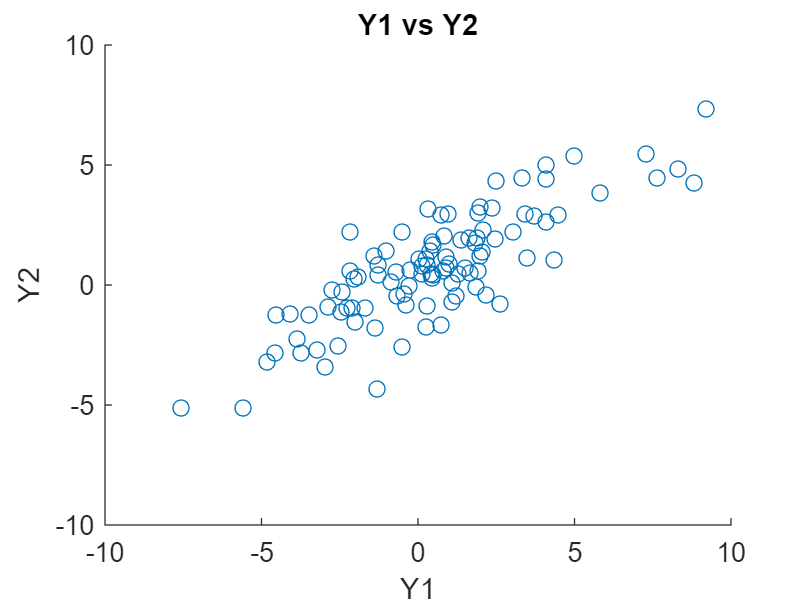

Svs = repmat(Sv,N,1);   % create stacked Sv
Hs = repmat(H,N,1);     % create stacked H matrix
Qk = randn(3,100);      % generate 100 samples of y1,y2,y3
yx = Hs* X + Svs*Qk;
y = yx(1:3,:);          % take just first 3 rows since matrix is stacked 

s1 = scatter(y(1,:), y(2,:));
xlim([-10,10]); ylim([-10,10]);
xlabel('Y1');ylabel('Y2');
title('Y1 vs Y2')

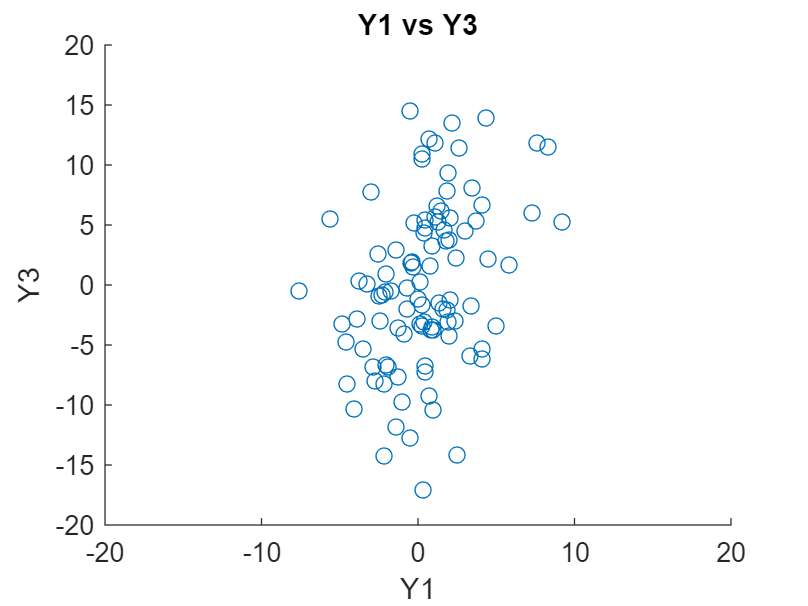

s2 = scatter(y(1,:), y(3,:));
xlim([-20,20]); ylim([-20,20]);
xlabel('Y1');ylabel('Y3');
title('Y1 vs Y3')

s3 = scatter(y(2,:),y(3,:));
xlim([-20,20]); ylim([-20,20]);
xlabel('Y2');ylabel('Y3');
title('Y2 vs Y3')

% Part B
% Calculate new covariance matrix using random msmts
R = cov(y');
disp("R_sampled = "); disp(R)

R_sampled = 
    9.2818    5.8676    8.5497
    5.8676    5.4301   -3.1355
    8.5497   -3.1355   55.4077




% Part C
% 3 SAMPLES
% build block diag matrix of R
R3 = cell(3);
for i=1:3
    for j=1:3
        if i==j
            R3{i} = [R3{i};R];
        else
            R3{i} = [R3{i};zeros(3)];
        end
    end
end
R3 = cat(2, R3{:}); % convert to 2D matrix
H3 = [H;H;H];
% build stacked Y
y3 = [y(1:3,1);y(1:3,2);y(1:3,3)];
X3 = inv(H3'*inv(R3)*H3)*H3'*inv(R3)*y3;
disp('X (3 samples) = '); disp(X3)

X (3 samples) = 
    1.9110
    2.6660
   -3.5412




% calculate error covariance
P3_err = inv(H3'*inv(R3)*H3);
disp('P_err (3 samples) = '); disp(P3_err)

P_err (3 samples) = 
    3.0939    1.9559    2.8499
    1.9559    1.8100   -1.0452
    2.8499   -1.0452   18.4692




% 10 SAMPLES
% build block diag matrix of R
R10= cell(10);
H10 = []; y10=[];
for i= 1:10
    H10 = [H10;H];
    y10 = [y10;y(1:3,i)];
    for j=1:10
        if i==j
            R10{i} = [R10{i};R];
        else
            R10{i} = [R10{i};zeros(3)];
        end
    end
end
R10 = cat(2, R10{:}); % convert to 2D matrix
X10 = inv(H10'*inv(R10)*H10)*H10'*inv(R10)*y10;
disp('X (10 samples) = '); disp(X10)

X (10 samples) = 
    2.3133
    2.4193
    0.8046




% calculate error covariance
P10_err = inv(H10'*inv(R10)*H10);
disp('P_err (10 samples) = '); disp(P10_err)

P_err (10 samples) = 
    0.9282    0.5868    0.8550
    0.5868    0.5430   -0.3135
    0.8550   -0.3135    5.5408




% 100 SAMPLES
% build block diag matrix of R
H100 = []; y100=[];
R100= cell(100);
H100 = []; y100=[];
for i= 1:100
    H100 = [H100;H];
    y100 = [y100;y(1:3,i)];
    for j=1:100
        if i==j
            R100{i} = [R100{i};R];
        else
            R100{i} = [R100{i};zeros(3)];
        end
    end
end
R100 = cat(2, R100{:}); % convert to 2D matrix
X100 = inv(H100'*inv(R100)*H100)*H100'*inv(R100)*y100;
disp('X (100 samples) = '); disp(X100)

X (100 samples) = 
    0.5308
    0.7536
    0.4757




% calculate error covariance
P100_err = inv(H100'*inv(R100)*H100);
disp('P_err (100 samples) = '); disp(P100_err)

P_err (100 samples) = 
    0.0928    0.0587    0.0855
    0.0587    0.0543   -0.0314
    0.0855   -0.0314    0.5541




%%%%%%%%%%%%%%%%

% Part D - weighted LS with actual msmts
Rnom = [8, 5.15, 6.5; 5.15, 5 ,-4.07; 6.5, -4.07, 50];
ymsmt = importdata("OneDrive - Microsoft/Documents/school/ASEN5044DynAnal/hw6problem5data.csv");
% ymsmt = importdata("hw6problem5data.csv");
R = Rnom;       % use R matrix associated with data sensor
Rmsmt = cov(ymsmt');
H30 = []; y30=[]; R30 = cell(30);
for i= 1:30
    H30 = [H30;H];
    y30 = [y30;ymsmt(1:3,i)];
    for j=1:30
        if i==j
            R30{i} = [R30{i};R];
        else
            R30{i} = [R30{i};zeros(3)];
        end
    end
end
R30 = cat(2, R30{:}); % convert to 2D matrix
X30 = inv(H30'*inv(R30)*H30)*H30'*inv(R30)*y30;
disp('X (30 samples) = '); disp(X30)

X (30 samples) = 
    4.3935
  -16.5495
   42.4159




P30_err = inv(H30'*inv(R30)*H30);
disp('P_err (30 samples) = '); disp(P30_err)

P_err (30 samples) = 
    0.2667    0.1717    0.2167
    0.1717    0.1667   -0.1357
    0.2167   -0.1357    1.6667





% Part E - batch unweighted LS
X30_unweighted = inv(H30'*H30)*H30'*y30;
disp('X (30 samples unweighted ls) = '); disp(X30_unweighted)

X (30 samples unweighted ls) = 
    4.3935
  -16.5495
   42.4159



P30u_err = inv(H30'*H30);
disp('P_err (30 samples unweighted ls) = '); disp(P30u_err)

P_err (30 samples unweighted ls) = 
    0.0333         0         0
         0    0.0333         0
         0         0    0.0333



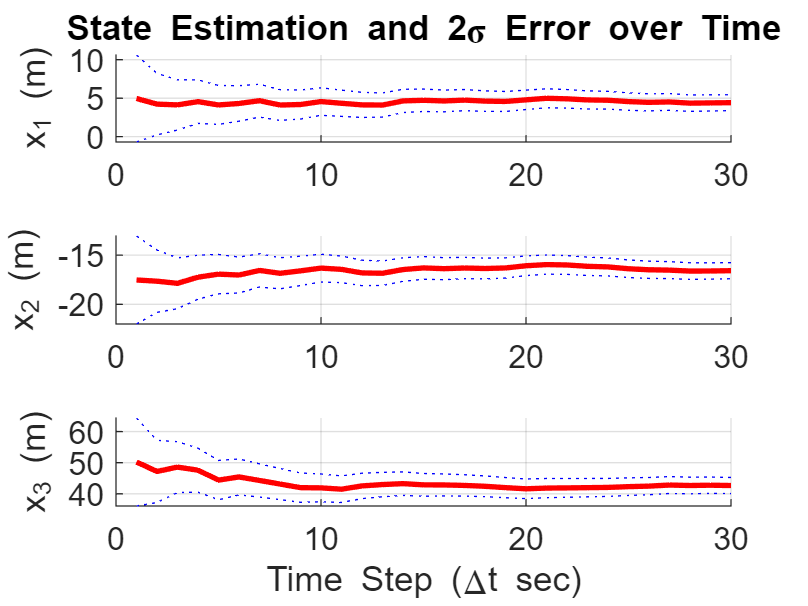


% Part F - recursive weighted LS
% Step 1: initialize estimator and initial values
% estimate x0
PArr = []; xhatArr = []; xhat = [];
sigma = []; H = eye(3);

xhat = inv(H' * inv(Rnom) * H) * H' * inv(Rnom) * ymsmt(:,1);
P = Rnom; % same as inv(I*inv(R)*I)

PArr(:,:,1) = P;
xhatArr(:,:,1) = xhat;
for k = 1:30
   K = P * H' * inv(H * P * H' + Rnom);
   sigma(:,k) = 2 * sqrt(diag(P));
   xhat = xhat + K * (ymsmt(:,k) - H * xhat);
   P = P - K * H * P;
   % Save data in arrays.
   xhatArr = [xhatArr xhat];
   PArr(:,:,k+1) = P;
end

% Plot the results.
close all; % close all figures
figure; % open a new figure
set(gcf,'Color','white');
k = 1 : 30;
subplot(3,1,1); hold on;
plot(k, xhatArr(1,2:31), 'r-', 'LineWidth', 2);
plot(k, sigma(1,:) + xhatArr(1,2:31), 'b:' )
plot(k, -sigma(1,:) + xhatArr(1,2:31), 'b:' )
set(gca,'FontSize',12);
title('State Estimation and 2\sigma Error over Time');
ylabel('x_1 (m)')

subplot(3,1,2); hold on;
plot(k, xhatArr(2,2:31), 'r-', 'LineWidth', 2);
plot(k, sigma(2,:) + xhatArr(2,2:31), 'b:' )
plot(k, -sigma(2,:) + xhatArr(2,2:31), 'b:' )
set(gca,'FontSize',12);
ylabel('x_2 (m)')

subplot(3,1,3); hold on;
plot(k, xhatArr(3,2:31), 'r-', 'LineWidth', 2);
plot(k, sigma(3,:) + xhatArr(3,2:31), 'b:' )
plot(k, -sigma(3,:) + xhatArr(3,2:31), 'b:' )
set(gca,'FontSize',12);
ylabel('x_3 (m)')
xlabel('Time Step (\Deltat sec)')

subplot(3,1,1)
grid on
ax = gca;
chart = ax.Children(2);
subplot(3,1,2)
grid on
ax = gca;
chart = ax.Children(3);
subplot(3,1,3)
grid on